We want to simulate the movement of a random walker using coin flips.

- How do you simulate a coin flip? The function `rand` draws a random number between 1 and 0. We partition this range such that a number <0.5 means a step to the left, and otherwise it means a step to the right.

Define simulation parameters:

Nsteps = 100; %Number of steps (coin flips, in this case)

Define the initial condition:

Pos(1)=0;

Take the first step:

CoinFlip=rand; %Draw a random number

To now decide whether I'm going to move to the right or the left, I need an if-statement.

if CoinFlip>0.5  %move right
    Pos(2)=Pos(1)+1;
else  %move left
    Pos(2)=Pos(1)-1;
end

%right is positive direction, left is negative direction
Pos

Pos =      0     1    -2    -3    -4    -3    -2    -1    -2    -1    -2    -1    -2    -1    -2    -1    -2    -1     0     1     0     1     0    -1    -2    -1    -2    -3    -2    -1     0     1     2     3     2     1     0     1     0    -1     0    -1     0    -1    -2    -3    -2    -3    -4    -5


Calculate the whole trajectory for this one random walker.

1.) Write a for-loop that keeps track of the position of the walker for each time point.

2.) Generate a vector that tells you the time step for each index within the Pos vector.

3.) Make a plot of your trajectory.

Time(1)=0;
Time(2)=1;
for i=3:Nsteps
    Time(i)=i-1;
    CoinFlip=rand;
    if CoinFlip>0.5  %move right
        Pos(i)=Pos(i-1)+1;
    else  %move left
        Pos(i)=Pos(i-1)-1;
    end
end

And now the plot:

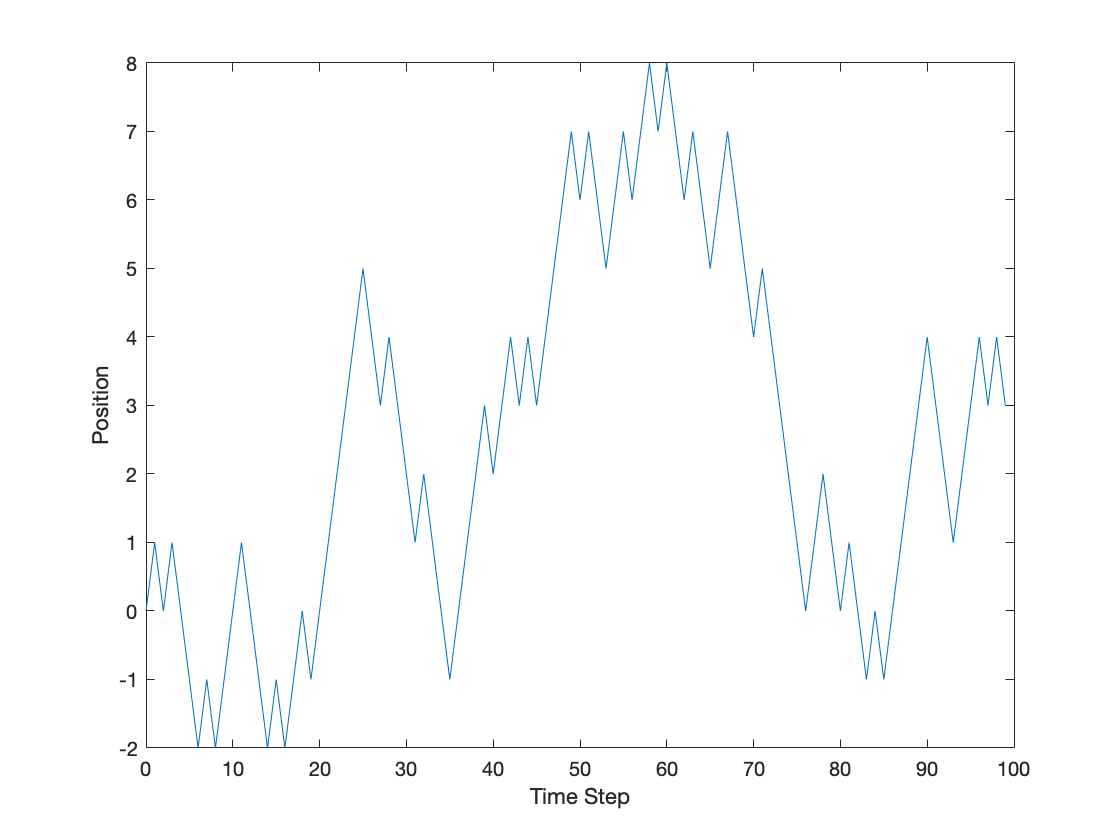

plot(Time, Pos);
xlabel('Time Step')
ylabel('Position')

In order to check my analytical calculations I need to perform this simulation for many walkers. Let's say

Nwalkers=100;

%{
The Pos matrix will look like this:

W1Pos1 W1Pos2 W1Pos3...
W2Pos1 W2Pos2 W2Pos3...
.
.
.

%}

Since now we need to keep track of multiple walkers, we'll define a position matrix. The rows of this matrix correspond to each walker. The columns correspond to each time point.

I need to set the initial condition of my walkers to be zero. This means that I need the first column of my matrix to be zero. To make this easy, we'll just define a matrix of size Nwalkers times Nsteps full of zeros.

PosMatrix=zeros(Nwalkers, Nsteps); % #rows, #columns

Now we're ready to perform this simulation using nested for-loops.

for i=1:Nwalkers
    for j=2:Nsteps
        Time(i)=i-1;
        CoinFlip=rand;
        if CoinFlip>0.5  %move right
            PosMatrix(i,j)=PosMatrix(i,j-1)+1;
        else  %move left
            PosMatrix(i,j)=PosMatrix(i,j-1)-1;
        end
    end
end

Finally, I make the plot.

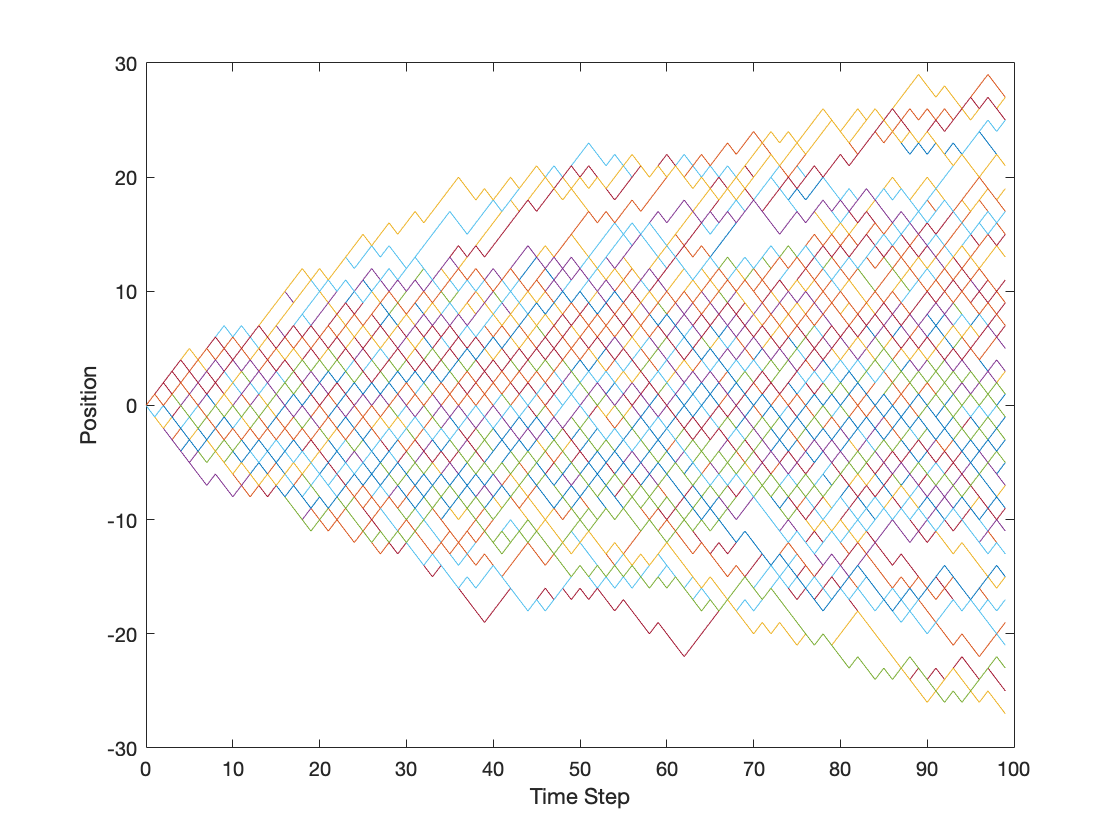

%We use the "'" operation to transpose the matrix.
%(transpose turns columns into rows and rows into columns, to make it easy for MATLAB to plot)
plot(Time, PosMatrix')
xlabel('Time Step')
ylabel('Position')

**Bonus Info:** The easiest way to retrieve a single column in MATLAB is using the following code:

PosMatrix(:, 7) %the seventh column of PosMatrix. ":" means 'everything along that dimension'

ans =     -4
     0
    -4
    -2
     4
     2
     4
    -2
     2
    -2


We want to calculate the statistics coming out of this simulation. Before that, let's plot the distribution of location of the random walker for different time points.

Plot the distribution of random walkers at time step 50.

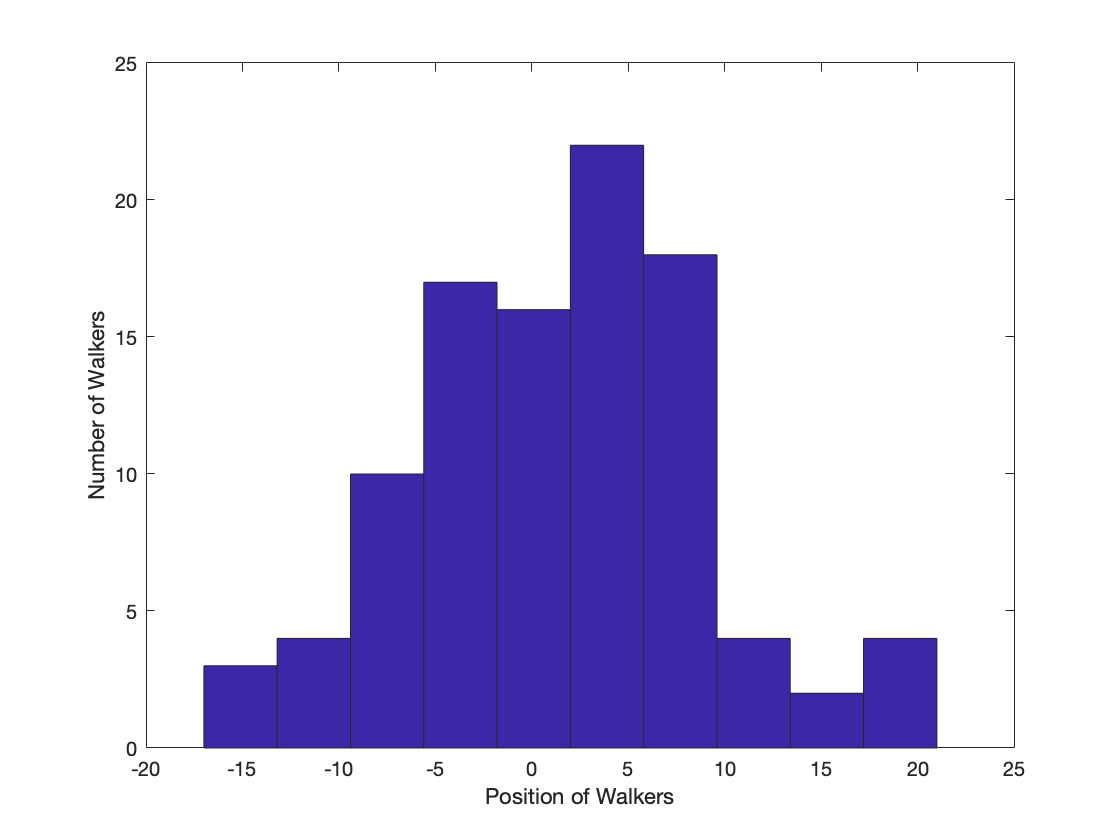

hist(PosMatrix(:,50))
xlabel('Position of Walkers')
ylabel('Number of Walkers')

Calculate the mean-squared displacement at time point 50. To do this, we need to learn about how to operate with vectors a little more.

a=[1,2,3,4,5,6]

a =      1     2     3     4     5     6


a+1

ans =      2     3     4     5     6     7


a*2

ans =      2     4     6     8    10    12


Note however, that you get an error if you try to do a^2. MATLAB thinks you're trying to square an entire matrix, when really you want to square each element of a matrix. To do that, we use the elementwise operator "."

PosSquare50=PosMatrix(:, 50).^2

PosSquare50 =      1
    49
    49
     9
    25
    25
     1
    49
     1
    49


Now sum all squared displacements

SumPosSquare50=sum(PosSquare50)

SumPosSquare50 = 6332

Finally, divide by Nwalkers to get the mean-squared displacement

MSD50=SumPosSquare50/Nwalkers

MSD50 = 63.3200

I just calculated the mean-squared displacement (MSD) for time point 50. Now, I want to calculate it for all time points.

First, square each element in the matrix.

PosSquare=PosMatrix.^2;

Then, add up the columns to get the sum of the squared displacements from each time point.

SumPosSquare=sum(PosSquare);

Finally, divide by the number of walkers to get the MSD at each time point

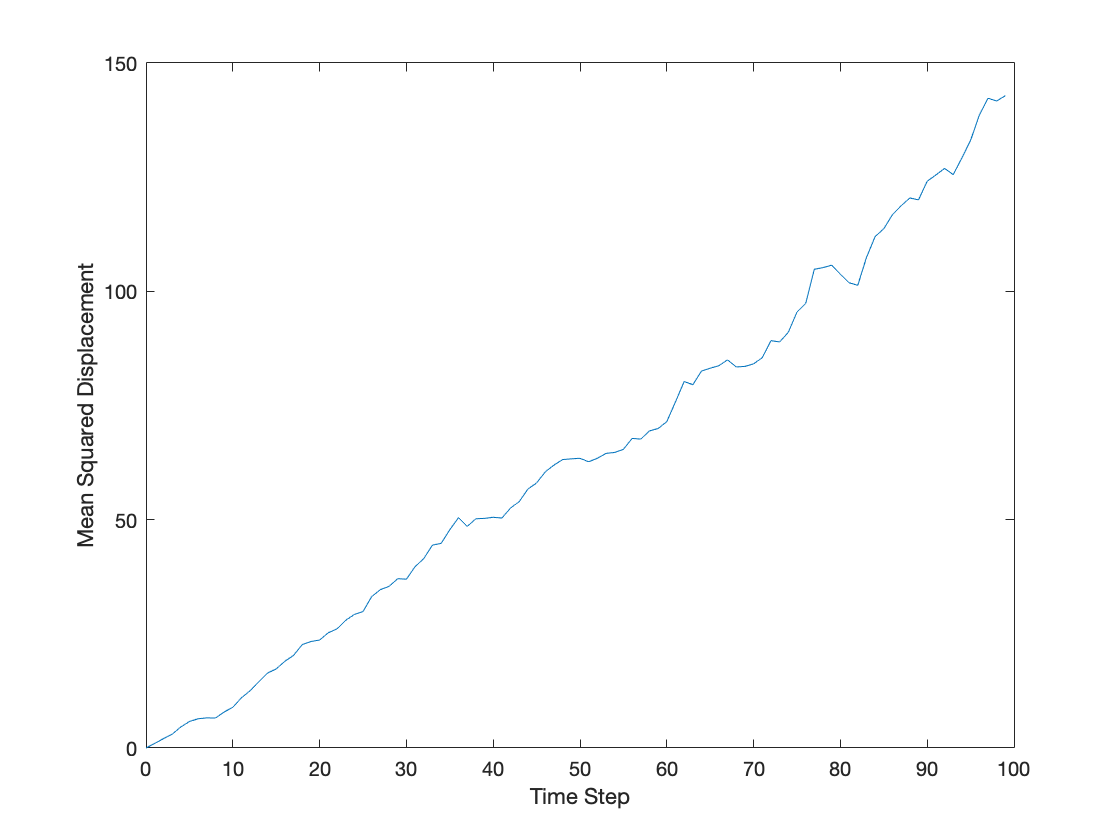

MSD=SumPosSquare/Nwalkers;
plot(Time, MSD)
xlabel('Time Step')
ylabel('Mean Squared Displacement')